clear all
close all

syms x y z
%constants
r_coil=0.5e-2;
r_wire=0.5e-3;
I = 3150;
c = 3*10^8;
mu_0 = 4*pi*10^-7;
k = mu_0/(4*pi);
t = 3.4e-6;

I/t

ans = 9.2647e+08

Spherical circle loop

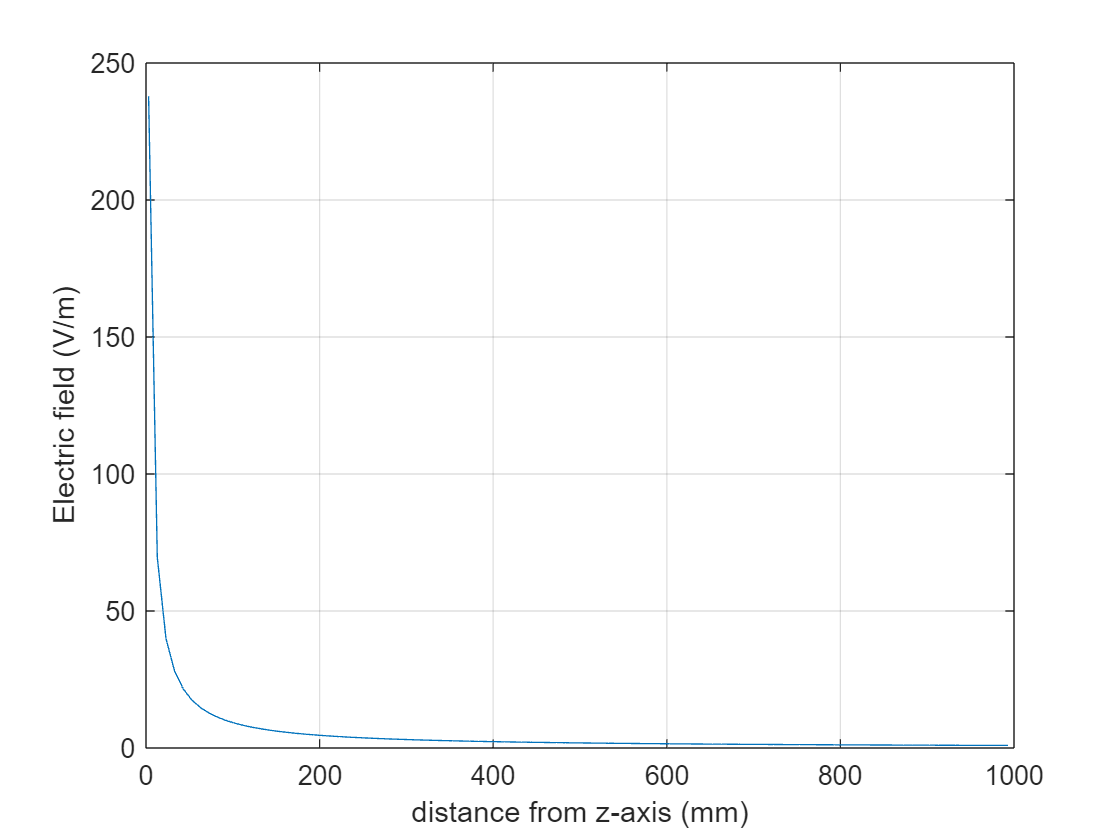

%observing point coordinates
x_obs =0;
y_obs =0.5e-2;

z_plot = 3e-3:1e-2:100e-2;
%z_test = 0:0.1e-3:10e-2;

i = 1;
f = 1;
j = 1;
q = 1;
s = 1;
A_phi_x_array = [];
A_phi_y_array = [];
for z_obs = 3e-3:1e-2:100e-2
    r_obs = sqrt(x_obs^2+y_obs^2+z_obs^2);
    phi_obs = atan(y_obs/x_obs);
    theta_obs = acos(z_obs./sqrt(x_obs^2+y_obs^2+z_obs.^2));

    %r_obs_square = sqrt((x_obs-x)^2+(y_obs-y)^2+(z_obs-z)^2);
    
    fun_x = @(phi) (k*I*(r_coil.*-sin(phi)))./sqrt(r_coil^2+r_obs.^2-2*r_coil.*r_obs*sin(theta_obs)*cos(phi));
    fun_y = @(phi) (k*I*(r_coil.*cos(phi)))./sqrt(r_coil^2+r_obs.^2-2*r_coil.*r_obs*sin(theta_obs)*cos(phi));
    A_phi_x = integral(fun_x,0,2*pi);
    A_phi_y = integral(fun_y,0,2*pi);
    A_phix(j) = A_phi_x;
    j = j+1;
    A_phiy(q) = A_phi_y;
    q = q+1;
    V_m_int(i) = sqrt(A_phi_y^2+A_phi_x^2)/t;
    i = i + 1;
    A_phi_x_array = [A_phi_x_array,A_phix];
    A_phi_y_array = [A_phi_y_array,A_phiy];

    fun_square = @(x) k*I./sqrt((-x).^2+(z_obs)^2);
    A_square = integral(fun_square, -0.5e-2, 0.5e-2);
    Asquare(s) = A_square;
    s = s+1;
    V_m_int_square(f) = A_square/t;
    f = f+1;
end

plot(z_plot*1000,V_m_int_square)
grid on
hold on
%plot(z_plot*1000,V_m_int_square)

xlabel("distance from z-axis (mm)")
ylabel("Electric field (V/m)")

%plot(z_test,-3.5*log(z_test-0.01))
%plot(z_plot*1000,0.5./z_plot*max(z_plot)-1.2)
%plot(z_plot*1000,-log(z_plot)/max(z_plot))
V_m_near = V_m_int_square(1)

V_m_near = 237.8798

V_m_far = V_m_int_square(end)

V_m_far = 0.9330

area = 2.5e-2

area = 0.0250

emf = V_m_far*area*27000

emf = 629.7734

current = emf/1e9

current = 6.2977e-07

%ratio = V_m_near/V_m_far
%legend ('circular loop', '1/x')